# **drawEllipse**

# **fillEllipse**

Draw the Ellipse arc

## Description

 Parametric equation of an elipse is

$x=x_c +a\;\mathrm{cos}\;t$, $y=y_c +b\;\mathrm{sin}\;t$,    $0\le t<2\pi$.

where *a, b *are the ellipse semi axes, and *t *is a sweep angle.

## Syntax

drawEllipse( a, b, xc, yc)

fillEllipse( c, a, b, xc, yc)

drawEllipse( a, b, xc, yc, rot)

drawEllipse( a, b, xc, yc, rot, t1, t2)

drawEllipse( a, b, xc, yc, rot, t1, t2,'-pie'|'-seg')

drawEllipse(__, '-np', np)

drawEllipse(__, LineSpec)

p = drawEllipse(__)

## Description

drawEllipse( a, b,xc,yc) draw the elipse with major axis a , minor axis b with enter at (xc,yc).

drawEllipse( a, b, xc, yc, rot) rotated by the angle *rot *in CCLW direction around center. 

drawEllipse( a, b, xc, yc, rot, t1, t2) draw elliptic arc

drawEllipse( a, b, xc, yc, rot, t1, t2,'-pie'|'-seg') draw elliptic pie or segment

drawEllipse( __, LineSpec)  sets the line style, line width, and color.

drawEllipse( __,'-np',np) set the number of points on the output curve.

p = drawEllipse(__) returns structure with output data.

## Method

For calculation of the coordinates of the curve **drawEllipse **call function **evalEllipse( a,b,xc,yc,rot,t)  **which returns coordinates *x *and *y *of the curve at given parameters t . For usage of **evalEllipse **see Example 1.

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**c - **fill color

**a, b **- semi major axis (real scalar)

**xc - **x-coordinate of the center (real scalar)

**yc **- y-coordinate of the center (real scalar)

### **Optional Input Argumnts**

**rot** - rotation angle about the center in degrees, CCLW direction >0, CLW direction is < 0.

**t1 **- start sweep angle in degrees)

**t2 **- central sweep angle in degrees)

**'-pie'|'-seg'** - draw pie or segment

### Optional Name-Value Pair Input Arguments

**'-np',** **np **- number of points along the curve ( scalar integer value > 2)

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with the fields

- p.xk, p.yk - key points: 1=start,2=end,3=center

- p.th - tangent angle: 1=start,2=end 

- p.color - line color

## Examples

### Example 1

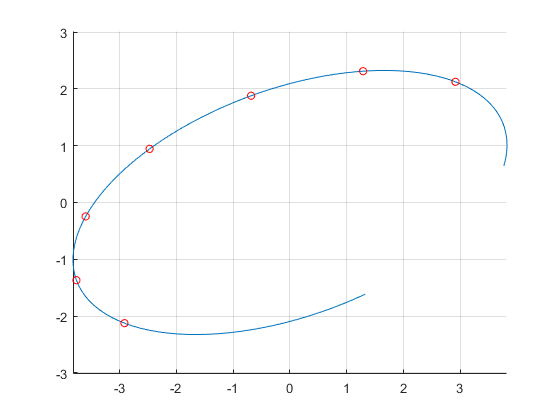

%Data 
a = 4;
b = 2;
% plot
figure
hold on
axis equal
[x,y] = evalEllipse(a,b,0,0,20,linspace(-20,280));
plot(x,y)
[x,y] = evalEllipse(a,b,0,0,20,[30,60,90,120,150,180,210]);
scatter(x,y,30,'r')
grid on

### Example 2

%Data 
xc = 0;
yc = 0;
a = 4;
b = 2;
t1 = 30;
t2 = 120;
figure
hold on
axis equal
E1 = drawEllipse(a,b,0,0,0,10,60,'-pie')

E1 = struct with fields:
       xk: [3.9392 1.3681 0]
       yk: [0.3473 1.8794 0]
       th: [109.4254 169.6859]
    color: 'k'


E2 = drawEllipse(a,b*3,xc,yc,30,t1,t2,'-seg','LineWidth',2,'Color','r','-np',10)

E2 = struct with fields:
       xk: [1.5000 -4.5000 0]
       yk: [4.3301 0.8660 0]
       th: [141.0517 -81.0517]
    color: [1 0 0]


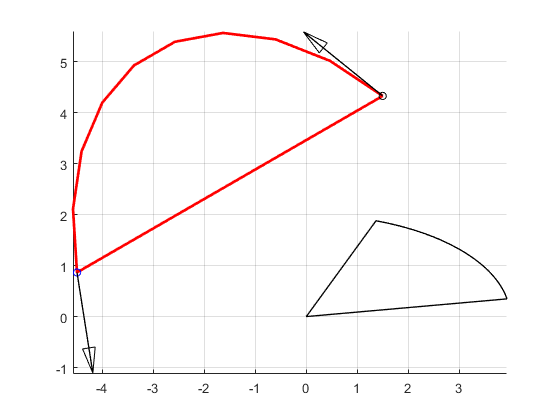

scatter(E2.xk(1),E2.yk(1),30,'k')
scatter(E2.xk(2),E2.yk(2),30,'b')
drawArrow(2,0.5,0.25,E2.xk(1),E2.yk(1),'-rtheta',2,E2.th(1))
drawArrow(2,0.5,0.25,E2.xk(2),E2.yk(2),'-rtheta',2,E2.th(2))
grid on

### Example 3

figure
hold on
axis equal
p = fillEllipse('m',2,1,1,1,'-np',215);
p = fillEllipse('y',1,0.5,1,1,30,-20,120,'-sec','-np',215)

p = struct with fields:
    xk: [1.8993 0.6034 1]
    yk: [1.3217 1.3396 1]
    th: [83.9476 -144.9616]


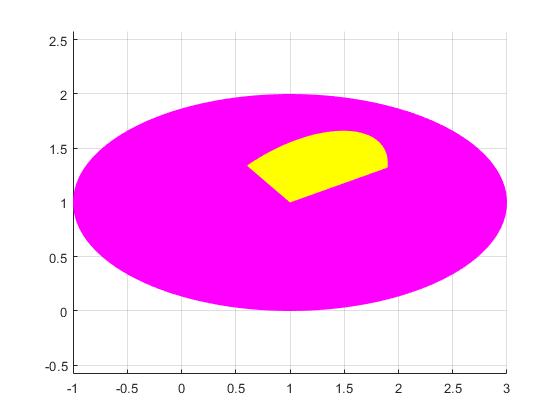

grid on

### Example 4

% intercept errors
figure
hold on
axis equal
p = drawEllipse(2,1,0,0,20,'-np',15)
grid on

## **See Also**

## References